load("600Ohmout_chip1.mat")


Vout_array = [Vout_without_calib, Vout_plus_calib, Vout_minus_calib, Vout_mean_calib]

Vout_array =    -1.1562   -1.1551   -1.1551   -1.1551
   -1.1729   -1.1724   -1.1724   -1.1724
   -1.1892   -1.1896   -1.1896   -1.1896
   -1.2052   -1.2063   -1.2063   -1.2063
   -1.2232   -1.2226   -1.2226   -1.2226
   -1.2387   -1.2388   -1.2388   -1.2388
   -1.2564   -1.2546   -1.2546   -1.2546
   -1.2713   -1.2702   -1.2702   -1.2702
   -1.2860   -1.2856   -1.2856   -1.2856
   -1.3026   -1.3004   -1.3004   -1.3004


Vout = Vout_array(:,4);

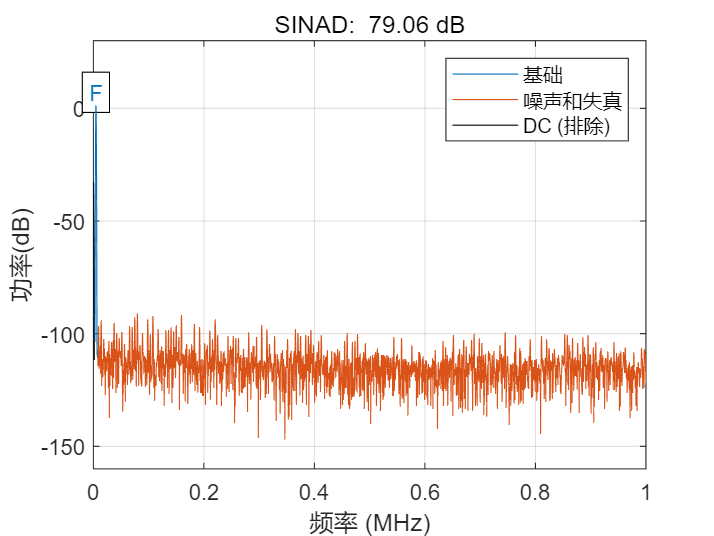

fs = 2E6;
sinad(Vout, fs);

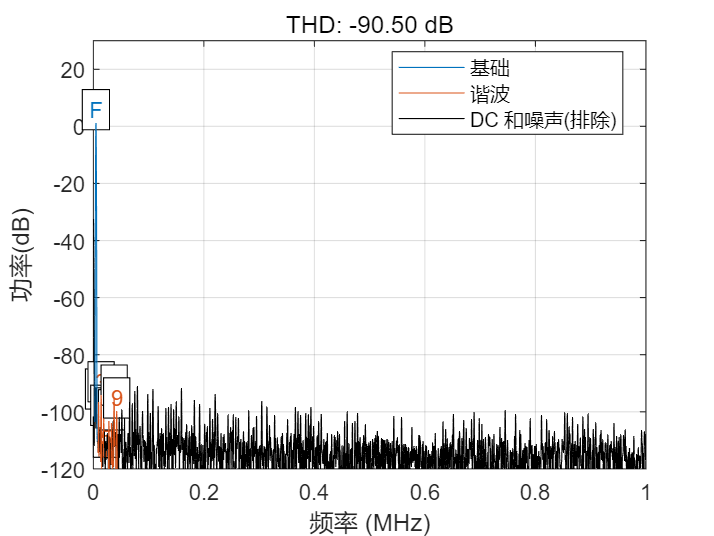



thd(Vout, fs, 9, 'aliased');

## Quantization

Vref = 1.8;
N = 16;

LSB = 2*Vref / 2^(N);
quan = zeros(length(Vout),1);
tic
for i=1:length(Vout)
    if (Vout(i)>0)
        quan(i) = floor(Vout(i)/LSB);
    else
        quan(i) = floor(Vout(i)/LSB)+1;
    end
end

Vout_quan = quan .* LSB;
toc

历时 0.006756 秒。


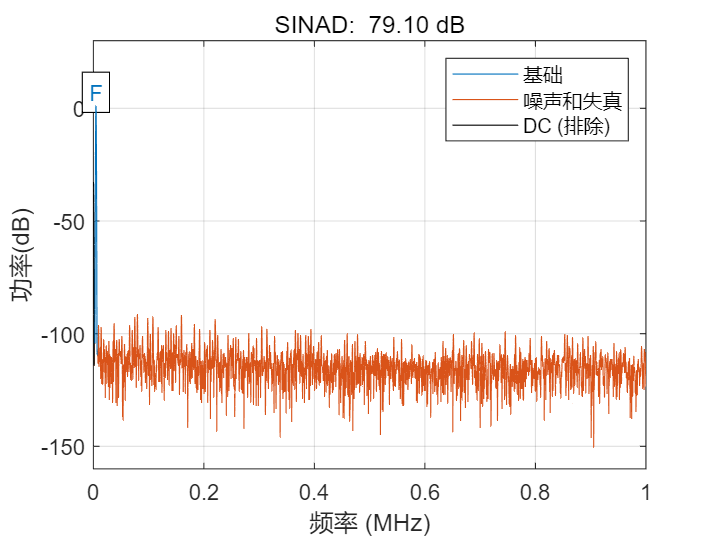

ans = 79.0997

sinad(Vout_quan, fs)

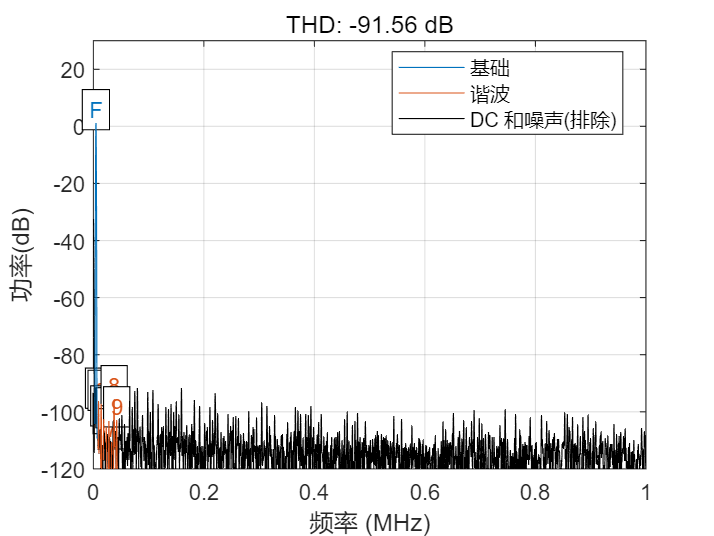

ans = -91.5639

thd(Vout_quan, fs, 9, 'aliased')


% way-2:
tic
% negetive = Vout < 0;
quan2 = floor(Vout / LSB);

Vout_quan2 = quan2 .* LSB;
toc

历时 0.006774 秒。


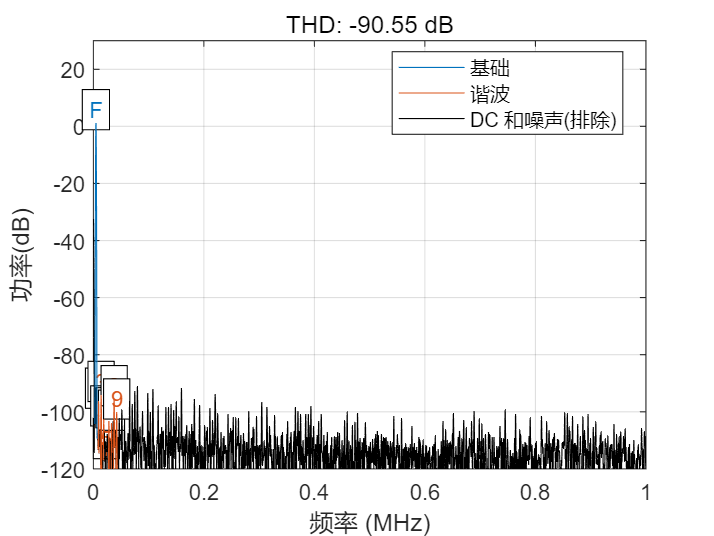

ans = -90.5525

thd(Vout_quan2, fs, 9, 'aliased')